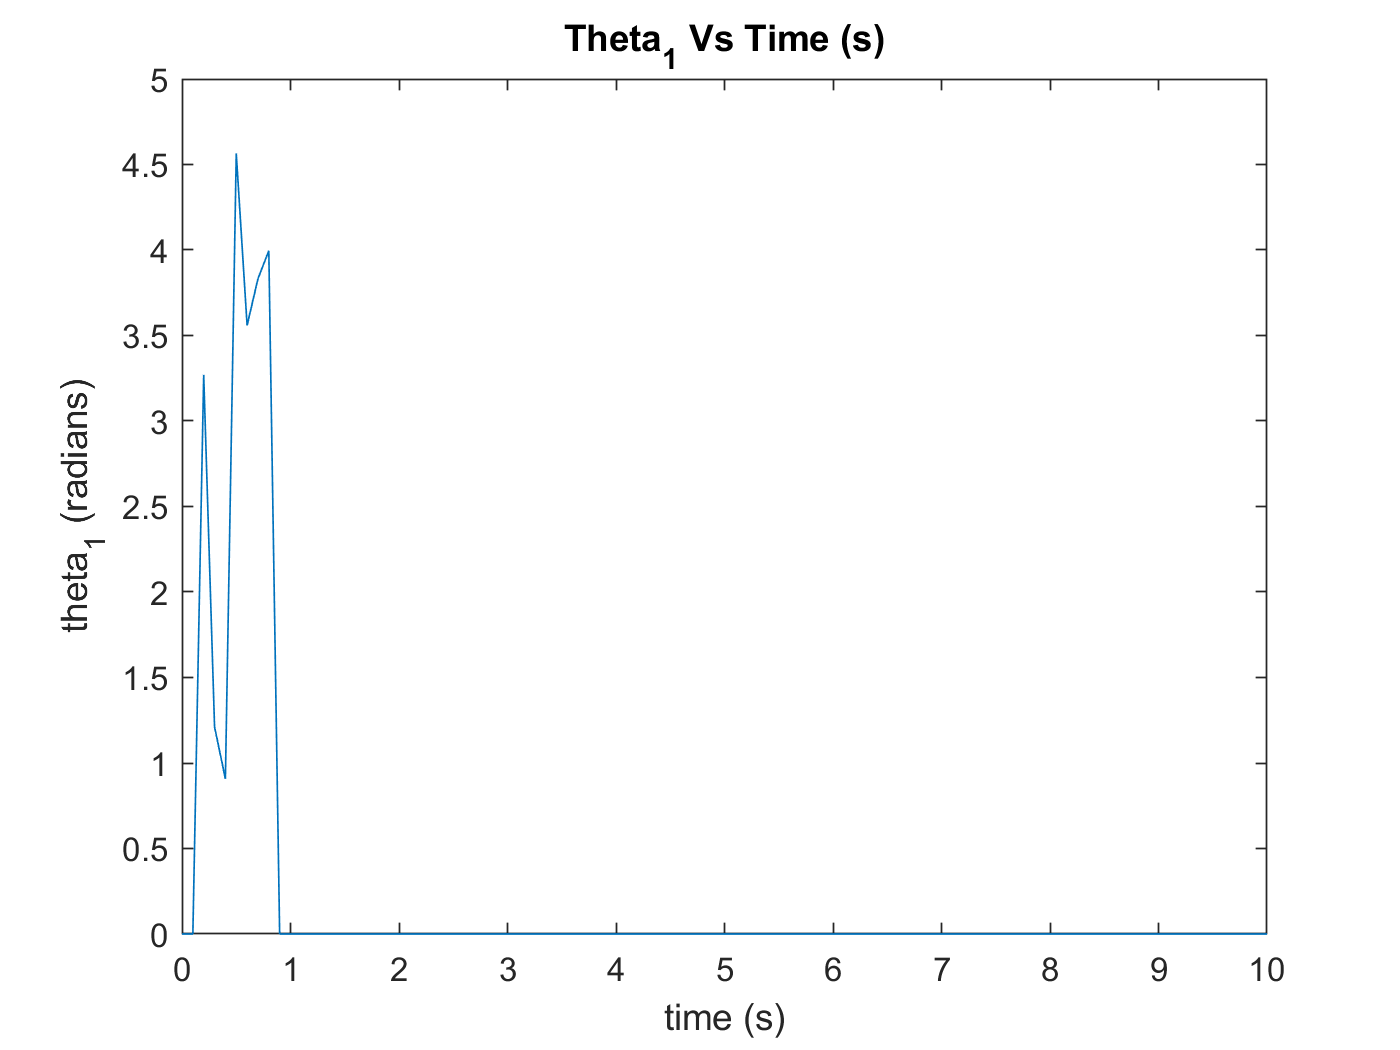

% housekeeping
clc
clear

% definitions
m=[1 1];
l=[0.01 1];
h=0.1;   % stepsize
t=0:h:10;


M = 4;
N = length(t); % Number of grid points 
v = zeros(M,N); % Initialise variable representing numerical solution 
x=zeros(2,N); % intialize x coordinates
y=zeros(2,N); % initialize y coordinates
v(:,1) = [0; 0; pi/4; 0]; % Initial condition 



% This loop executes explicit Euler 
for i = 1:N-1
    x(1,i)=l(1)*sin(v(1,i)) ;
    x(2,i)=l(1)*sin(v(1,i))+l(2)*sin(v(3,i));
    y(1,i)=-l(1)*cos(v(1,i));
    y(2,i)= -l(1)*cos(v(1,i))-l(2)*cos(v(3,i));
%     f_alg = @(y_next) [y(:,i) + (h/2)*(f(t(i+1), y_next) + f(t(i), y(:,i))) - y_next] % The algebraic equation we have to solve at each time step 
%     y_guess =y(:,i); 
%     y(:,i+1) = fsolve(f_alg, y_guess); 
    omega=double_Pend(t(i),v(:,i),m,l);
    v(:,i+1) = v(:,i) + h*omega;
    v(1,i+1)=mod(v(1,i+1),2*pi);
    v(3,i+1)=mod(v(3,i+1),2*pi);
end
% 
% for i = 1:N-1
%     
%     plot(0,0,'.','markersize',20)
%     hold on
%     plot(x(1,i),y(1,i),'.','markersize',20)
%     plot(x(2,i),y(2,i),'.','markersize',20)
% 
%     plot([0 x(1,i)],[0 y(1,i)],'k')
%     plot([x(1,i) x(2,i)],[y(1,i) y(2,i)],'g');
%     xlim([-2 2])
%     ylim([-2 2])
%     drawnow
%     hold off
% end


% plotting theta against time
plot(t,v(1,:))
xlabel('time (s)')
ylabel('theta_1 (radians)')
title('Theta_1 Vs Time (s)')

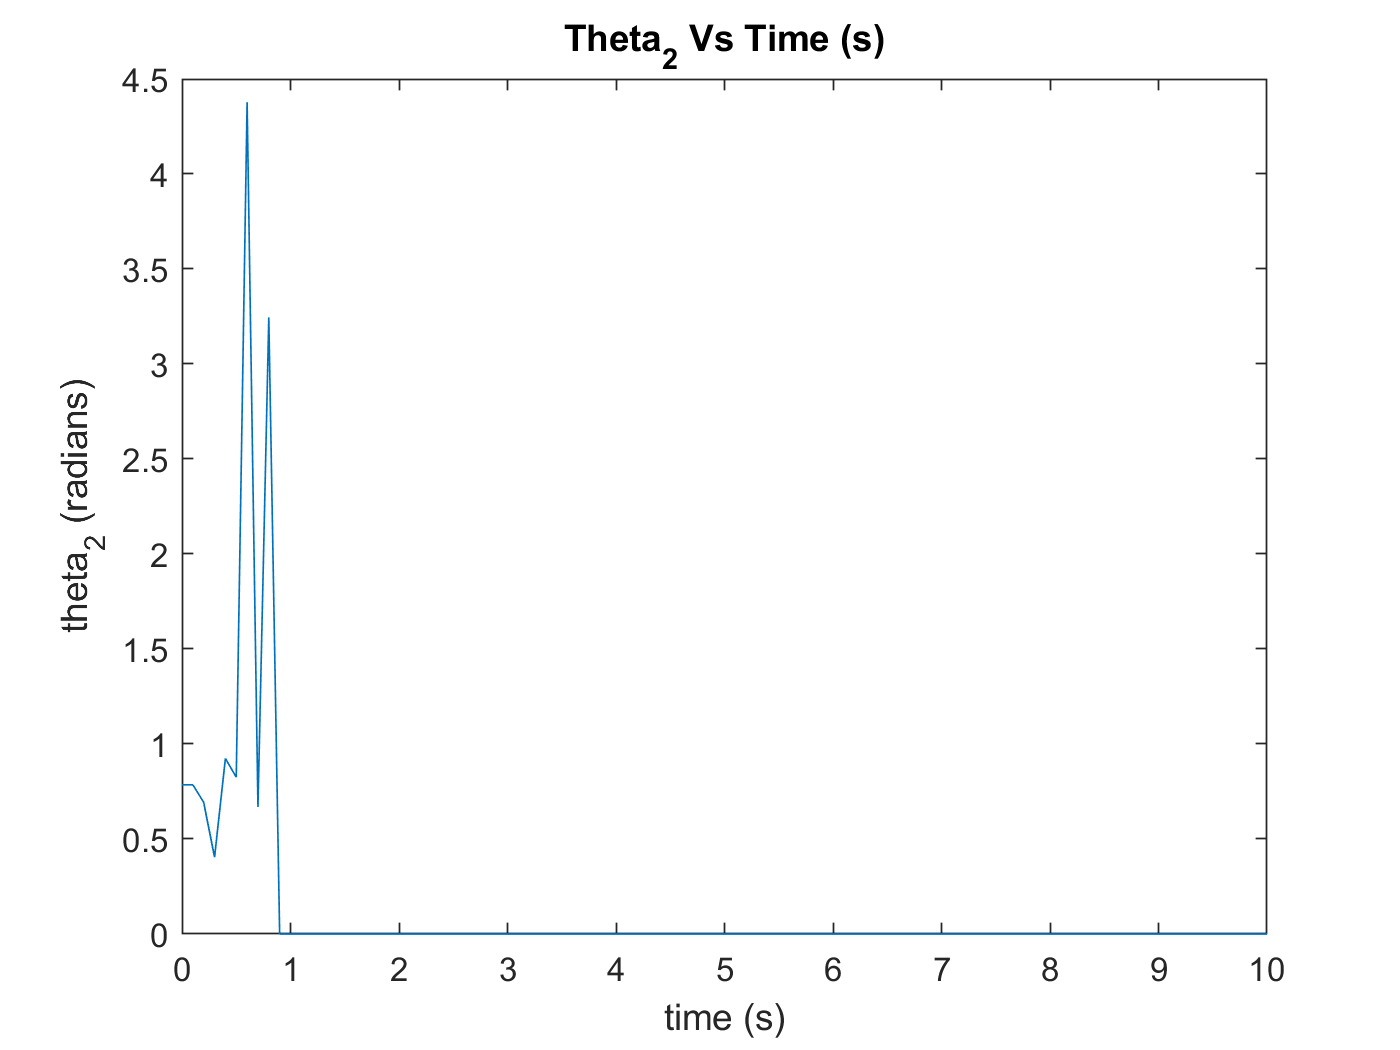


plot(t,v(3,:))
xlabel('time (s)')
ylabel('theta_2 (radians)')
title('Theta_2 Vs Time (s)')

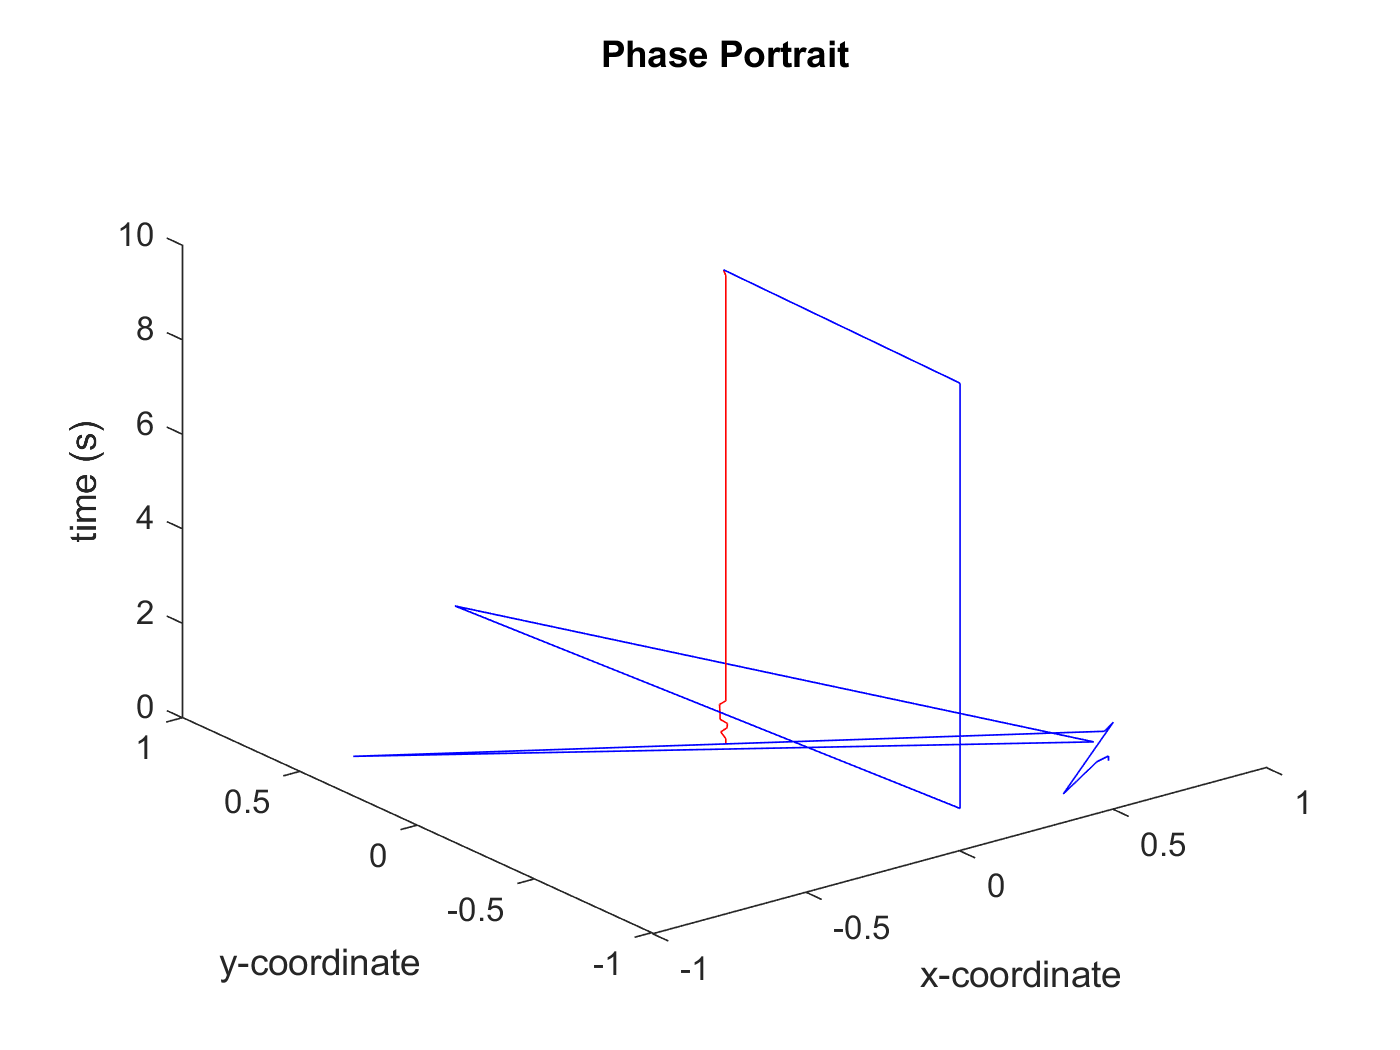


% plotting (x1,y1) and (x2,y2) in same plot
plot3(x(1,:),y(1,:),t,'r')
hold on
plot3(x(2,:),y(2,:),t,'b')
xlabel('x-coordinate')
ylabel('y-coordinate')
zlabel('time (s)')
title('Phase Portrait')
hold off